# Generating cost

## Import the data

### Import DAM LBMP data in 2019 from NYISO database

clear;
% Import hourly DAM LBMP data in Jan 2019
priceFileDir = "D:\EERL\ny_academic_model\data\2019_DAM_LBMP_Generator\";
priceFileName = '2019*damlbmp_gen.csv';
DAMPriceDataShoreJan = fileDatastore(priceFileDir + priceFileName, "ReadFcn", @importDAMPriceData, "UniformRead", true);
priceAll = readall(DAMPriceDataShoreJan);
clear DAMPriceDataShoreJan;

% Format datetime to match the generation dataset
priceAll.Date = dateshift(priceAll.TimeStamp, 'start', 'day');
priceAll.Hour = priceAll.TimeStamp.Hour;

### Import generation data in 2019 from RGGI database

genFileDir = "D:\EERL\ny_academic_model\data\EPA_AMPD\2019\";
genFileName = "emission*.csv";
generationDataStore = fileDatastore(genFileDir + genFileName, "ReadFcn", @importGenerationData, "UniformRead", true);
genAll = readall(generationDataStore);
clear generationDataStore

### Import RGGI to NYCA reference table

% Import the reference table from RGGI to NYISO NYCA database
RGGI2NYCA2019 = importRGGI2NYCA("D:\EERL\ny_academic_model\data\EPA_AMPD\RGGI_2_NYCA_2019.xlsx");
generatorCombiner = RGGI2NYCA2019(:, ["NYISOname", "PTID", "FacilityName", "FacilityID", "UnitID", "NYAMUnit", "Region", "UnitType", "FuelType", "NamePlateRatingMW"]);
% Exclude generators that are not included in NYAM units
generatorCombiner = generatorCombiner(generatorCombiner.NYAMUnit ~= 'NA',:);
% Exclude generators fueling on wood and refuse (renewable energy)
generatorCombiner = generatorCombiner(generatorCombiner.FuelType ~= "Wood" & generatorCombiner.FuelType ~= "Refuse", :);
% Remove unused categories
generatorCombiner.NYISOname = removecats(generatorCombiner.NYISOname);
generatorCombiner.PTID = removecats(generatorCombiner.PTID);
generatorCombiner.FacilityName = removecats(generatorCombiner.FacilityName);
generatorCombiner.FacilityID = removecats(generatorCombiner.FacilityID);
generatorCombiner.UnitID = removecats(generatorCombiner.UnitID);
generatorCombiner.NYAMUnit = removecats(generatorCombiner.NYAMUnit);
generatorCombiner.Region = removecats(generatorCombiner.Region);
generatorCombiner.UnitType = removecats(generatorCombiner.UnitType);
generatorCombiner.FuelType = removecats(generatorCombiner.FuelType);

## Combine data tables

### Combine the generation data with the reference table

% Join tables generation data with the reference table
jiontGenAll = outerjoin(genAll,generatorCombiner,'Type', 'right', 'Keys',{'FacilityName','FacilityID','UnitID'},...
    "LeftVariables", {'Date', 'Hour', 'GrossLoadMW', 'OperatingTime', 'HeatInputMMBtu'}, "RightVariables", ...
    {'NYISOname', 'PTID', 'FacilityName', 'FacilityID', 'NYAMUnit', 'Region', 'UnitType', 'FuelType', 'NamePlateRatingMW'});

### Combine the joint generation data with price data

% Join tables
GenPriceAll = outerjoin(jiontGenAll,priceAll,'Type','left','Keys',{'Date','Hour','PTID'},'MergeKeys',true, ...
    "LeftVariables", {'Date', 'Hour', 'NYISOname', 'PTID', 'NYAMUnit', 'Region', 'UnitType', 'FuelType', 'GrossLoadMW', 'HeatInputMMBtu', 'NamePlateRatingMW', 'OperatingTime'}, ...
    "RightVariables", {'LBMPMWHr', 'MarginalCostCongestionMWHr', 'MarginalCostLossesMWHr'});
GenPriceAll.Dayofyear = day(GenPriceAll.Date, 'dayofyear');

### Remove missing data

% Find the generators with missing price data
groupsummary(GenPriceAll(ismissing(GenPriceAll.LBMPMWHr), :), ["NYISOname", "PTID"])

ans = 2×3 table
           NYISOname            PTID     GroupCount
    _______________________    ______    __________

    Bethlehem Energy Center    323570      26280   
    Independence               23970       35040   


% Remove generators with missing price data
cleanedGenPriceAll = rmmissing(GenPriceAll, "DataVariables", "LBMPMWHr");

## Subset data table with NYAM units and visualize the raw data

% Subset the generator summary table by NYAM units
GenPriceA2FCC = cleanedGenPriceAll(cleanedGenPriceAll.NYAMUnit == "A2F-CC", :);
GenPriceA2FST = cleanedGenPriceAll(cleanedGenPriceAll.NYAMUnit == "A2F-ST", :);
GenPriceGHIST = cleanedGenPriceAll(cleanedGenPriceAll.NYAMUnit == "GHI-ST", :);
GenPriceJCC = cleanedGenPriceAll(cleanedGenPriceAll.NYAMUnit == "J-CC", :);
GenPriceJCT = cleanedGenPriceAll(cleanedGenPriceAll.NYAMUnit == "J-CT", :);
GenPriceJST = cleanedGenPriceAll(cleanedGenPriceAll.NYAMUnit == "J-ST", :);
GenPriceKCT = cleanedGenPriceAll(cleanedGenPriceAll.NYAMUnit == "K-CT", :);
GenPriceKST = cleanedGenPriceAll(cleanedGenPriceAll.NYAMUnit == "K-ST", :);

### Plot generation and price of all generators (no aggregation)

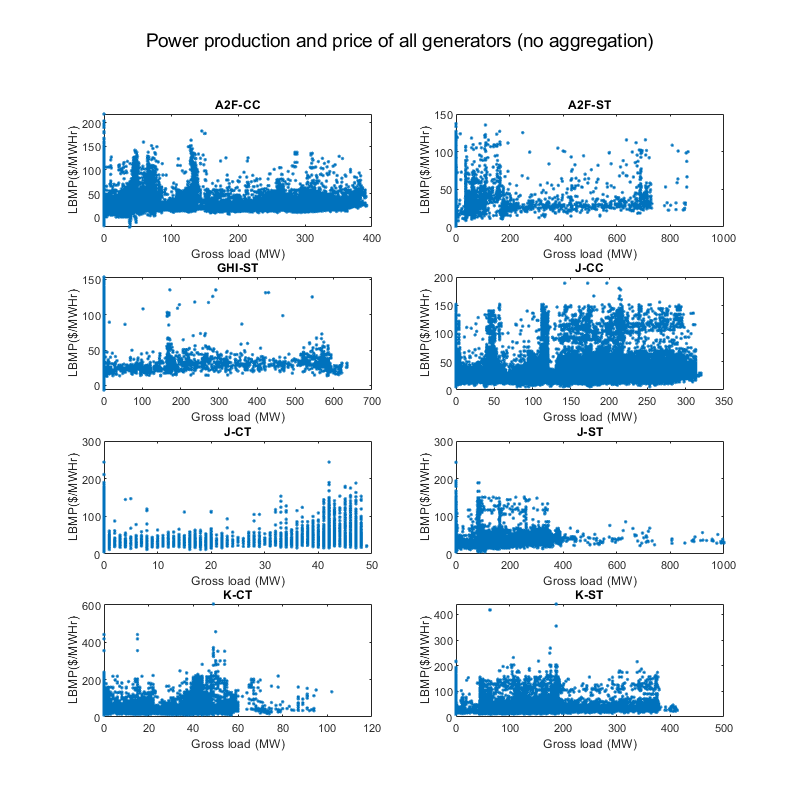

figure;
subplot(4,2,1);
scatter(GenPriceA2FCC.GrossLoadMW, GenPriceA2FCC.LBMPMWHr, ".");
title("A2F-CC"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,2);
scatter(GenPriceA2FST.GrossLoadMW, GenPriceA2FST.LBMPMWHr, ".");
title("A2F-ST"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,3);
scatter(GenPriceGHIST.GrossLoadMW, GenPriceGHIST.LBMPMWHr, ".");
title("GHI-ST"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,4);
scatter(GenPriceJCC.GrossLoadMW, GenPriceJCC.LBMPMWHr, ".");
title("J-CC"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,5);
scatter(GenPriceJCT.GrossLoadMW, GenPriceJCT.LBMPMWHr, ".");
title("J-CT"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,6);
scatter(GenPriceJST.GrossLoadMW, GenPriceJST.LBMPMWHr, ".");
title("J-ST"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,7);
scatter(GenPriceKCT.GrossLoadMW, GenPriceKCT.LBMPMWHr, ".");
title("K-CT"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,8);
scatter(GenPriceKST.GrossLoadMW, GenPriceKST.LBMPMWHr, ".");
title("K-ST"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
suptitle("Power production and price of all generators (no aggregation)");
set(gcf, 'Units', 'Pixels', 'Position', [100, 100, 800, 800]);

## Calculate average price of aggregated units

### Calculate gross revenue of each generators in each hour

% Gross revenue = gross load * price
GenPriceA2FCC.GrossRevenue = GenPriceA2FCC.GrossLoadMW .* GenPriceA2FCC.LBMPMWHr;
GenPriceA2FST.GrossRevenue = GenPriceA2FST.GrossLoadMW .* GenPriceA2FST.LBMPMWHr;
GenPriceGHIST.GrossRevenue = GenPriceGHIST.GrossLoadMW .* GenPriceGHIST.LBMPMWHr;
GenPriceJCC.GrossRevenue = GenPriceJCC.GrossLoadMW .* GenPriceJCC.LBMPMWHr;
GenPriceJCT.GrossRevenue = GenPriceJCT.GrossLoadMW .* GenPriceJCT.LBMPMWHr;
GenPriceJST.GrossRevenue = GenPriceJST.GrossLoadMW .* GenPriceJST.LBMPMWHr;
GenPriceKCT.GrossRevenue = GenPriceKCT.GrossLoadMW .* GenPriceKCT.LBMPMWHr;
GenPriceKST.GrossRevenue = GenPriceKST.GrossLoadMW .* GenPriceKST.LBMPMWHr;

### Calcualte total power generation and total revenue of each aggregated units in each hour

sumGenPriceA2FCC = groupsummary(GenPriceA2FCC, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu", "GrossRevenue"]);
sumGenPriceA2FST = groupsummary(GenPriceA2FST, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu", "GrossRevenue"]);
sumGenPriceGHIST = groupsummary(GenPriceGHIST, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu", "GrossRevenue"]);
sumGenPriceJCC = groupsummary(GenPriceJCC, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu", "GrossRevenue"]);
sumGenPriceJCT = groupsummary(GenPriceJCT, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu", "GrossRevenue"]);
sumGenPriceJST = groupsummary(GenPriceJST, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu", "GrossRevenue"]);
sumGenPriceKCT = groupsummary(GenPriceKCT, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu", "GrossRevenue"]);
sumGenPriceKST = groupsummary(GenPriceKST, ["Date", "Hour"], "sum", ["GrossLoadMW", "HeatInputMMBtu", "GrossRevenue"]);

### Calculate average price of each aggregated units in each hour

sumGenPriceA2FCC.AveragePrice = sumGenPriceA2FCC.sum_GrossRevenue ./ sumGenPriceA2FCC.sum_GrossLoadMW;
sumGenPriceA2FST.AveragePrice = sumGenPriceA2FST.sum_GrossRevenue ./ sumGenPriceA2FST.sum_GrossLoadMW;
sumGenPriceGHIST.AveragePrice = sumGenPriceGHIST.sum_GrossRevenue ./ sumGenPriceGHIST.sum_GrossLoadMW;
sumGenPriceJCC.AveragePrice = sumGenPriceJCC.sum_GrossRevenue ./ sumGenPriceJCC.sum_GrossLoadMW;
sumGenPriceJCT.AveragePrice = sumGenPriceJCT.sum_GrossRevenue ./ sumGenPriceJCT.sum_GrossLoadMW;
sumGenPriceJST.AveragePrice = sumGenPriceJST.sum_GrossRevenue ./ sumGenPriceJST.sum_GrossLoadMW;
sumGenPriceKCT.AveragePrice = sumGenPriceKCT.sum_GrossRevenue ./ sumGenPriceKCT.sum_GrossLoadMW;
sumGenPriceKST.AveragePrice = sumGenPriceKST.sum_GrossRevenue ./ sumGenPriceKST.sum_GrossLoadMW;

% Add day of year variable to summary table
sumGenPriceA2FCC.Dayofyear = day(sumGenPriceA2FCC.Date, 'dayofyear');
sumGenPriceA2FST.Dayofyear = day(sumGenPriceA2FST.Date, 'dayofyear');
sumGenPriceGHIST.Dayofyear = day(sumGenPriceGHIST.Date, 'dayofyear');
sumGenPriceJCC.Dayofyear = day(sumGenPriceJCC.Date, 'dayofyear');
sumGenPriceJCT.Dayofyear = day(sumGenPriceJCT.Date, 'dayofyear');
sumGenPriceJST.Dayofyear = day(sumGenPriceJST.Date, 'dayofyear');
sumGenPriceKCT.Dayofyear = day(sumGenPriceKCT.Date, 'dayofyear');
sumGenPriceKST.Dayofyear = day(sumGenPriceKST.Date, 'dayofyear');

% Fill missing average price data with zero (due to zero total laod and zero total price)
sumGenPriceA2FCC = fillmissing(sumGenPriceA2FCC, "constant", 0, "DataVariables", "AveragePrice");
sumGenPriceA2FST = fillmissing(sumGenPriceA2FST, "constant", 0, "DataVariables", "AveragePrice");
sumGenPriceGHIST = fillmissing(sumGenPriceGHIST, "constant", 0, "DataVariables", "AveragePrice");
sumGenPriceJCC = fillmissing(sumGenPriceJCC, "constant", 0, "DataVariables", "AveragePrice");
sumGenPriceJCT = fillmissing(sumGenPriceJCT, "constant", 0, "DataVariables", "AveragePrice");
sumGenPriceJST = fillmissing(sumGenPriceJST, "constant", 0, "DataVariables", "AveragePrice");
sumGenPriceKCT = fillmissing(sumGenPriceKCT, "constant", 0, "DataVariables", "AveragePrice");
sumGenPriceKST = fillmissing(sumGenPriceKST, "constant", 0, "DataVariables", "AveragePrice");

### Plot average price of aggregated NYAM units

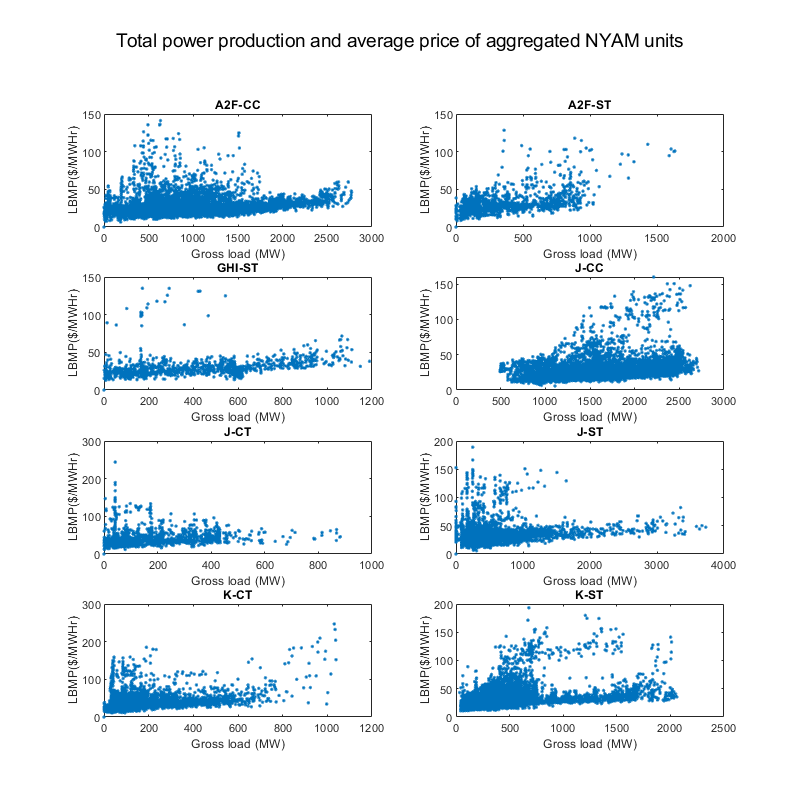

figure;
subplot(4,2,1);
scatter(sumGenPriceA2FCC.sum_GrossLoadMW, sumGenPriceA2FCC.AveragePrice, ".");
title("A2F-CC"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,2);
scatter(sumGenPriceA2FST.sum_GrossLoadMW, sumGenPriceA2FST.AveragePrice, ".");
title("A2F-ST"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,3);
scatter(sumGenPriceGHIST.sum_GrossLoadMW, sumGenPriceGHIST.AveragePrice, ".");
title("GHI-ST"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,4);
scatter(sumGenPriceJCC.sum_GrossLoadMW, sumGenPriceJCC.AveragePrice, ".");
title("J-CC"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,5);
scatter(sumGenPriceJCT.sum_GrossLoadMW, sumGenPriceJCT.AveragePrice, ".");
title("J-CT"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,6);
scatter(sumGenPriceJST.sum_GrossLoadMW, sumGenPriceJST.AveragePrice, ".");
title("J-ST"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,7);
scatter(sumGenPriceKCT.sum_GrossLoadMW, sumGenPriceKCT.AveragePrice, ".");
title("K-CT"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
subplot(4,2,8);
scatter(sumGenPriceKST.sum_GrossLoadMW, sumGenPriceKST.AveragePrice, ".");
title("K-ST"); xlabel("Gross load (MW)"); ylabel("LBMP($/MWHr)"); box on;
suptitle("Total power production and average price of aggregated NYAM units");
set(gcf, 'Units', 'Pixels', 'Position', [100, 100, 800, 800]);

### Fit quadratic function of total price and total production of NYAM units

Most of the data cannot be fitted into quadratic functions due to too many outliers with high price.

polyGenPriceA2FCC = polyfit(sumGenPriceA2FCC.sum_GrossLoadMW, sumGenPriceA2FCC.AveragePrice, 2)

polyGenPriceA2FCC =   -6.4773e-06     0.021582       13.867


polyGenPriceA2FST = polyfit(sumGenPriceA2FST.sum_GrossLoadMW, sumGenPriceA2FST.AveragePrice, 2)

polyGenPriceA2FST =   -6.3234e-05      0.11095       1.9649


polyGenPriceGHIST = polyfit(sumGenPriceGHIST.sum_GrossLoadMW, sumGenPriceGHIST.AveragePrice, 2)

polyGenPriceGHIST =   -7.7865e-05      0.10956      0.74237


polyGenPriceJCC = polyfit(sumGenPriceJCC.sum_GrossLoadMW, sumGenPriceJCC.AveragePrice, 2)

polyGenPriceJCC =    2.9451e-06    -0.001813       22.585


polyGenPriceJCT = polyfit(sumGenPriceJCT.sum_GrossLoadMW, sumGenPriceJCT.AveragePrice, 2)

polyGenPriceJCT =    -0.0003967      0.30254       3.0575


polyGenPriceJST = polyfit(sumGenPriceJST.sum_GrossLoadMW, sumGenPriceJST.AveragePrice, 2)

polyGenPriceJST =   -6.7319e-06     0.027255       18.915


polyGenPriceKCT = polyfit(sumGenPriceKCT.sum_GrossLoadMW, sumGenPriceKCT.AveragePrice, 2)

polyGenPriceKCT =    9.7824e-07      0.06589       25.123


polyGenPriceKST = polyfit(sumGenPriceKST.sum_GrossLoadMW, sumGenPriceKST.AveragePrice, 2)

polyGenPriceKST =   -1.7532e-05     0.046375       18.621


### Plot the fitted quadratic function and the original data

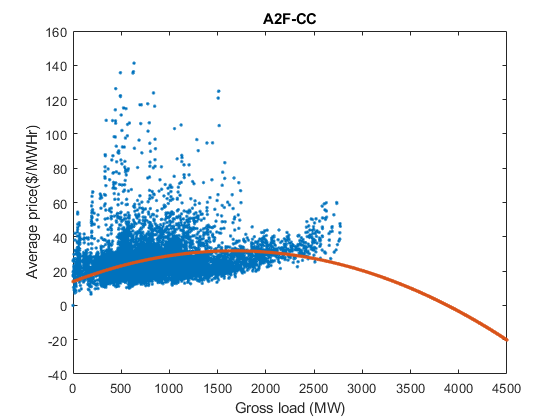

figure;
scatter(sumGenPriceA2FCC.sum_GrossLoadMW, sumGenPriceA2FCC.AveragePrice, ".");
title("A2F-CC"); xlabel("Gross load (MW)"); ylabel("Average price($/MWHr)");
hold on;
x = [0:4500]';
predGenPriceA2FCC = polyval(polyGenPriceA2FCC, x);
scatter(x, predGenPriceA2FCC, '.');
s = sprintf('y = (%f) x^2 + (%f) x + (%f)',polyGenPriceA2FCC(1), polyGenPriceA2FCC(2), polyGenPriceA2FCC(3));
text(1000, 3500, s);
hold off; box on;

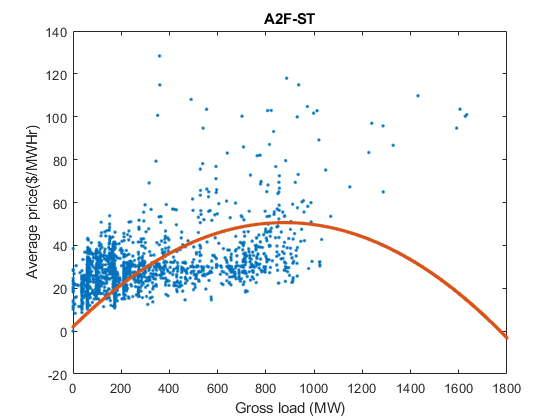

figure;
scatter(sumGenPriceA2FST.sum_GrossLoadMW, sumGenPriceA2FST.AveragePrice, ".");
title("A2F-ST"); xlabel("Gross load (MW)"); ylabel("Average price($/MWHr)");
hold on;
x = [0:1800]';
predGenPriceA2FST = polyval(polyGenPriceA2FST, x);
scatter(x, predGenPriceA2FST, '.');
s = sprintf('y = (%f) x^2 + (%f) x + (%f)',polyGenPriceA2FST(1), polyGenPriceA2FST(2), polyGenPriceA2FST(3));
text(400, 800, s);
hold off; box on;

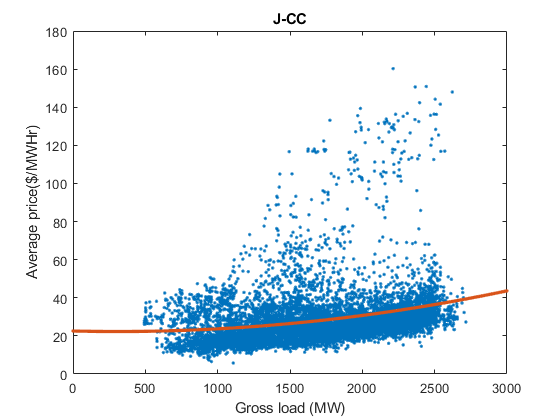

figure;
scatter(sumGenPriceJCC.sum_GrossLoadMW, sumGenPriceJCC.AveragePrice, ".");
title("J-CC"); xlabel("Gross load (MW)"); ylabel("Average price($/MWHr)");
hold on;
x = [0:3000]';
predGenPriceJCC = polyval(polyGenPriceJCC, x);
scatter(x, predGenPriceJCC, '.');
s = sprintf('y = (%f) x^2 + (%f) x + (%f)',polyGenPriceJCC(1), polyGenPriceJCC(2), polyGenPriceJCC(3));
text(400, 2200, s);
hold off; box on;

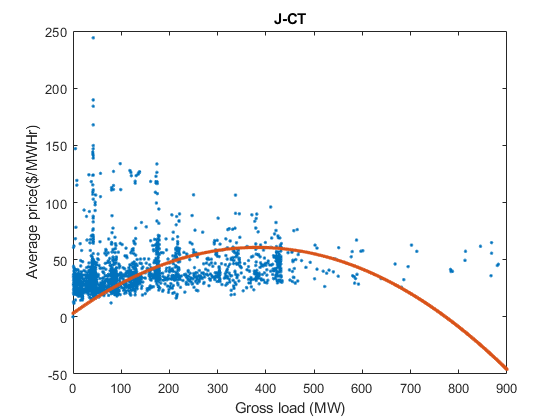

figure;
scatter(sumGenPriceJCT.sum_GrossLoadMW, sumGenPriceJCT.AveragePrice, ".");
title("J-CT"); xlabel("Gross load (MW)"); ylabel("Average price($/MWHr)");
hold on;
x = [0:900]';
predGenPriceJCT = polyval(polyGenPriceJCT, x);
scatter(x, predGenPriceJCT, '.');
s = sprintf('y = (%f) x^2 + (%f) x + (%f)',polyGenPriceJCT(1), polyGenPriceJCT(2), polyGenPriceJCT(3));
text(200, 6000, s);
hold off; box on;

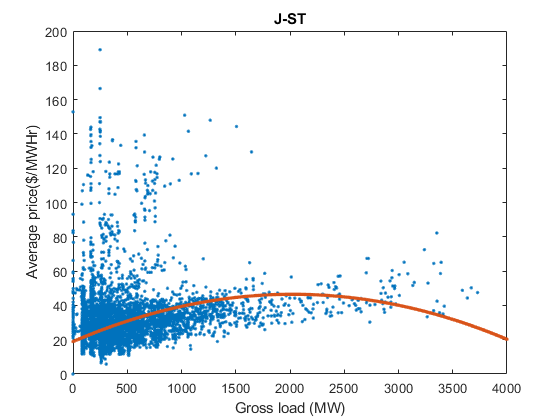

figure;
scatter(sumGenPriceJST.sum_GrossLoadMW, sumGenPriceJST.AveragePrice, ".");
title("J-ST"); xlabel("Gross load (MW)"); ylabel("Average price($/MWHr)");
hold on;
x = [0:4000]';
predGenPriceJST = polyval(polyGenPriceJST, x);
scatter(x, predGenPriceJST, '.');
s = sprintf('y = (%f) x^2 + (%f) x + (%f)',polyGenPriceJST(1), polyGenPriceJST(2), polyGenPriceJST(3));
text(1000, 2200, s);
hold off; box on;

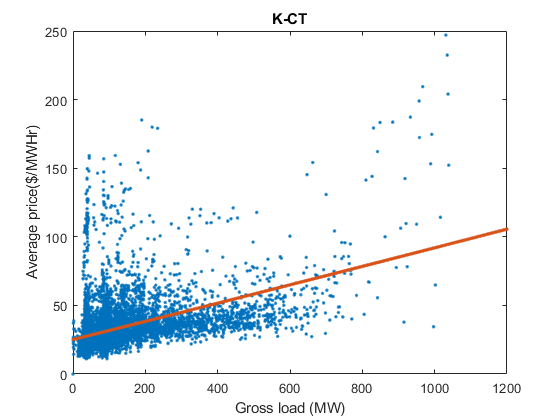

figure;
scatter(sumGenPriceKCT.sum_GrossLoadMW, sumGenPriceKCT.AveragePrice, ".");
title("K-CT"); xlabel("Gross load (MW)"); ylabel("Average price($/MWHr)");
hold on;
x = [0:1200]';
predGenPriceKCT = polyval(polyGenPriceKCT, x);
scatter(x, predGenPriceKCT, '.');
s = sprintf('y = (%f) x^2 + (%f) x + (%f)',polyGenPriceKCT(1), polyGenPriceKCT(2), polyGenPriceKCT(3));
text(200, 10000, s);
hold off; box on;

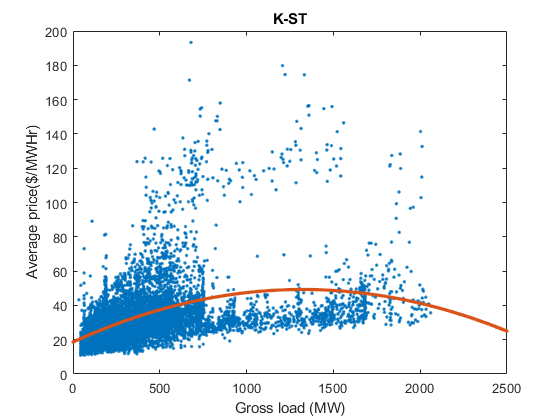

figure;
scatter(sumGenPriceKST.sum_GrossLoadMW, sumGenPriceKST.AveragePrice, ".");
title("K-ST"); xlabel("Gross load (MW)"); ylabel("Average price($/MWHr)");
hold on;
x = [0:2500]';
predGenPriceKST = polyval(polyGenPriceKST, x);
scatter(x, predGenPriceKST, '.');
s = sprintf('y = (%f) x^2 + (%f) x + (%f)',polyGenPriceKST(1), polyGenPriceKST(2), polyGenPriceKST(3));
text(500, 1400, s);
hold off; box on;

## Calculate marginal cost of aggregated units

% Find generators with non-zero generation
NZGenPriceA2FCC = GenPriceA2FCC(GenPriceA2FCC.GrossLoadMW ~= 0, :);
NZGenPriceA2FST = GenPriceA2FST(GenPriceA2FST.GrossLoadMW ~= 0, :);
NZGenPriceGHIST = GenPriceGHIST(GenPriceGHIST.GrossLoadMW ~= 0, :);
NZGenPriceJCC = GenPriceJCC(GenPriceJCC.GrossLoadMW ~= 0, :);
NZGenPriceJCT = GenPriceJCT(GenPriceJCT.GrossLoadMW ~= 0, :);
NZGenPriceJST = GenPriceJST(GenPriceJST.GrossLoadMW ~= 0, :);
NZGenPriceKCT = GenPriceKCT(GenPriceKCT.GrossLoadMW ~= 0, :);
NZGenPriceKST = GenPriceKST(GenPriceKST.GrossLoadMW ~= 0, :);

MarginalPriceA2FCC = groupsummary(NZGenPriceA2FCC, ["Date", "Hour"], "max", "LBMPMWHr");
MarginalPriceA2FST = groupsummary(NZGenPriceA2FST, ["Date", "Hour"], "max", "LBMPMWHr");
MarginalPriceGHIST = groupsummary(NZGenPriceGHIST, ["Date", "Hour"], "max", "LBMPMWHr");
MarginalPriceJCC = groupsummary(NZGenPriceJCC, ["Date", "Hour"], "max", "LBMPMWHr");
MarginalPriceJCT = groupsummary(NZGenPriceJCT, ["Date", "Hour"], "max", "LBMPMWHr");
MarginalPriceJST = groupsummary(NZGenPriceJST, ["Date", "Hour"], "max", "LBMPMWHr");
MarginalPriceKCT = groupsummary(NZGenPriceKCT, ["Date", "Hour"], "max", "LBMPMWHr");
MarginalPriceKST = groupsummary(NZGenPriceKST, ["Date", "Hour"], "max", "LBMPMWHr");

MarPriceTotGenA2FCC = outerjoin(MarginalPriceA2FCC, sumGenPriceA2FCC, "Type", "left", "Keys", ["Date", "Hour"], "MergeKeys",true, ...
    "LeftVariables", ["Date", "Hour", "max_LBMPMWHr"], "RightVariables", ["sum_GrossLoadMW", "sum_HeatInputMMBtu", "sum_GrossRevenue"]);
MarPriceTotGenA2FST = outerjoin(MarginalPriceA2FST, sumGenPriceA2FST, "Type", "left", "Keys", ["Date", "Hour"], "MergeKeys",true, ...
    "LeftVariables", ["Date", "Hour", "max_LBMPMWHr"], "RightVariables", ["sum_GrossLoadMW", "sum_HeatInputMMBtu", "sum_GrossRevenue"]);
MarPriceTotGenGHIST = outerjoin(MarginalPriceGHIST, sumGenPriceGHIST, "Type", "left", "Keys", ["Date", "Hour"], "MergeKeys",true, ...
    "LeftVariables", ["Date", "Hour", "max_LBMPMWHr"], "RightVariables", ["sum_GrossLoadMW", "sum_HeatInputMMBtu", "sum_GrossRevenue"]);
MarPriceTotGenJCC = outerjoin(MarginalPriceJCC, sumGenPriceJCC, "Type", "left", "Keys", ["Date", "Hour"], "MergeKeys",true, ...
    "LeftVariables", ["Date", "Hour", "max_LBMPMWHr"], "RightVariables", ["sum_GrossLoadMW", "sum_HeatInputMMBtu", "sum_GrossRevenue"]);
MarPriceTotGenJCT = outerjoin(MarginalPriceJCT, sumGenPriceJCT, "Type", "left", "Keys", ["Date", "Hour"], "MergeKeys",true, ...
    "LeftVariables", ["Date", "Hour", "max_LBMPMWHr"], "RightVariables", ["sum_GrossLoadMW", "sum_HeatInputMMBtu", "sum_GrossRevenue"]);
MarPriceTotGenJST = outerjoin(MarginalPriceJST, sumGenPriceJST, "Type", "left", "Keys", ["Date", "Hour"], "MergeKeys",true, ...
    "LeftVariables", ["Date", "Hour", "max_LBMPMWHr"], "RightVariables", ["sum_GrossLoadMW", "sum_HeatInputMMBtu", "sum_GrossRevenue"]);
MarPriceTotGenKCT = outerjoin(MarginalPriceKCT, sumGenPriceKCT, "Type", "left", "Keys", ["Date", "Hour"], "MergeKeys",true, ...
    "LeftVariables", ["Date", "Hour", "max_LBMPMWHr"], "RightVariables", ["sum_GrossLoadMW", "sum_HeatInputMMBtu", "sum_GrossRevenue"]);
MarPriceTotGenKST = outerjoin(MarginalPriceKST, sumGenPriceKST, "Type", "left", "Keys", ["Date", "Hour"], "MergeKeys",true, ...
    "LeftVariables", ["Date", "Hour", "max_LBMPMWHr"], "RightVariables", ["sum_GrossLoadMW", "sum_HeatInputMMBtu", "sum_GrossRevenue"]);

% Add day of year variable into marginal price table
MarPriceTotGenA2FCC.Dayofyear = day(MarPriceTotGenA2FCC.Date, 'dayofyear');
MarPriceTotGenA2FST.Dayofyear = day(MarPriceTotGenA2FST.Date, 'dayofyear');
MarPriceTotGenGHIST.Dayofyear = day(MarPriceTotGenGHIST.Date, 'dayofyear');
MarPriceTotGenJCC.Dayofyear = day(MarPriceTotGenJCC.Date, 'dayofyear');
MarPriceTotGenJCT.Dayofyear = day(MarPriceTotGenJCT.Date, 'dayofyear');
MarPriceTotGenJST.Dayofyear = day(MarPriceTotGenJST.Date, 'dayofyear');
MarPriceTotGenKCT.Dayofyear = day(MarPriceTotGenKCT.Date, 'dayofyear');
MarPriceTotGenKST.Dayofyear = day(MarPriceTotGenKST.Date, 'dayofyear');

### Plot marginal cost and average cost of each aggregated units

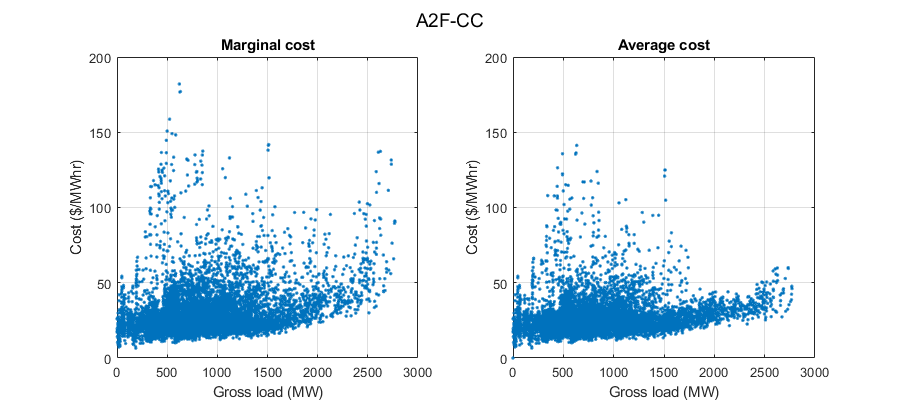

% A2FCC
figure;
subplot(1,2,1);
scatter(MarPriceTotGenA2FCC.sum_GrossLoadMW, MarPriceTotGenA2FCC.max_LBMPMWHr, ".");
title("Marginal cost"); box on; xlabel("Gross load (MW)"); ylabel("Cost ($/MWhr)"); grid on;
axis([0, 3000, 0, 200]);
subplot(1,2,2);
scatter(sumGenPriceA2FCC.sum_GrossLoadMW,sumGenPriceA2FCC.AveragePrice, '.');
title("Average cost"); box on; xlabel("Gross load (MW)"); ylabel("Cost ($/MWhr)"); grid on;
axis([0, 3000, 0, 200]);
suptitle("A2F-CC");
set(gcf, "Units", "Pixels", "Position", [100, 100, 900, 400]);

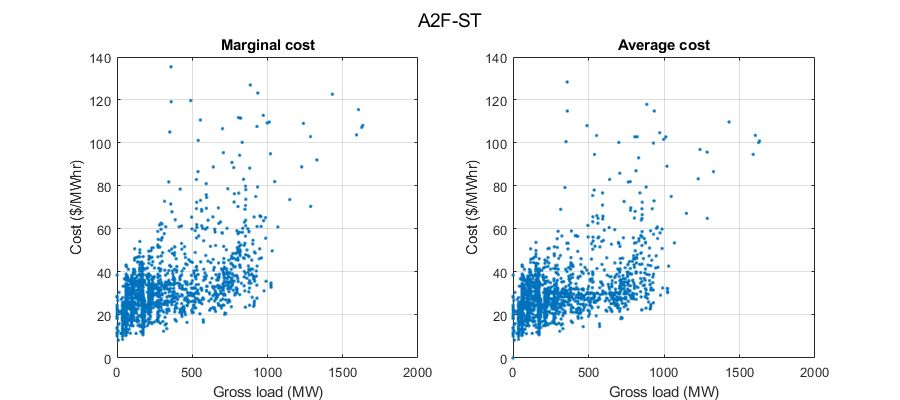

% A2FST
figure;
subplot(1,2,1);
scatter(MarPriceTotGenA2FST.sum_GrossLoadMW, MarPriceTotGenA2FST.max_LBMPMWHr, '.');
title("Marginal cost"); box on; xlabel("Gross load (MW)"); ylabel("Cost ($/MWhr)"); grid on;
subplot(1,2,2);
scatter(sumGenPriceA2FST.sum_GrossLoadMW,sumGenPriceA2FST.AveragePrice, '.');
title("Average cost"); box on; xlabel("Gross load (MW)"); ylabel("Cost ($/MWhr)"); grid on;
suptitle("A2F-ST");
set(gcf, "Units", "Pixels", "Position", [100, 100, 900, 400]);

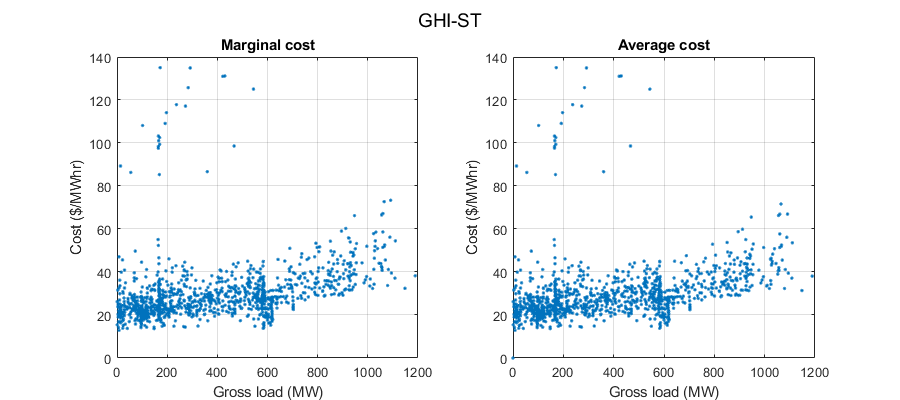

% GHIST
figure;
subplot(1,2,1);
scatter(MarPriceTotGenGHIST.sum_GrossLoadMW, MarPriceTotGenGHIST.max_LBMPMWHr, '.');
title("Marginal cost"); box on; xlabel("Gross load (MW)"); ylabel("Cost ($/MWhr)"); grid on;
subplot(1,2,2);
scatter(sumGenPriceGHIST.sum_GrossLoadMW,sumGenPriceGHIST.AveragePrice, '.');
title("Average cost"); box on; xlabel("Gross load (MW)"); ylabel("Cost ($/MWhr)"); grid on;
suptitle("GHI-ST");
set(gcf, "Units", "Pixels", "Position", [100, 100, 900, 400]);

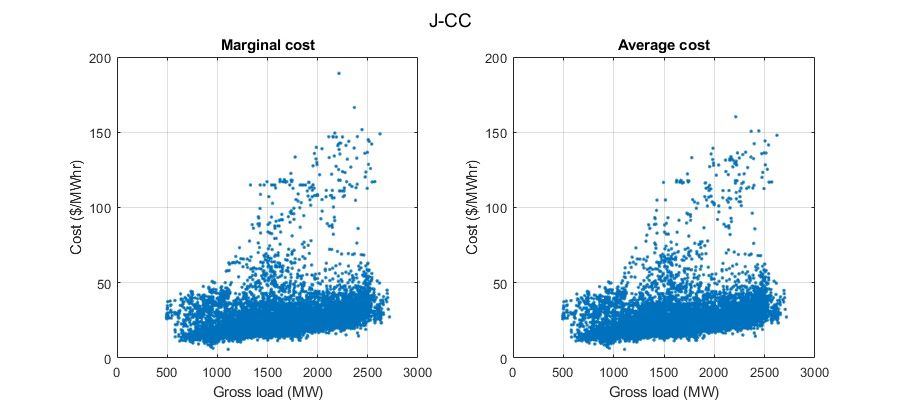

% JCC
figure;
subplot(1,2,1);
scatter(MarPriceTotGenJCC.sum_GrossLoadMW, MarPriceTotGenJCC.max_LBMPMWHr, '.');
title("Marginal cost"); box on; xlabel("Gross load (MW)"); ylabel("Cost ($/MWhr)"); grid on;
axis([0, 3000, 0, 200]);
subplot(1,2,2);
scatter(sumGenPriceJCC.sum_GrossLoadMW,sumGenPriceJCC.AveragePrice, '.');
title("Average cost"); box on; xlabel("Gross load (MW)"); ylabel("Cost ($/MWhr)"); grid on;
axis([0, 3000, 0, 200]);
suptitle("J-CC");
set(gcf, "Units", "Pixels", "Position", [100, 100, 900, 400]);

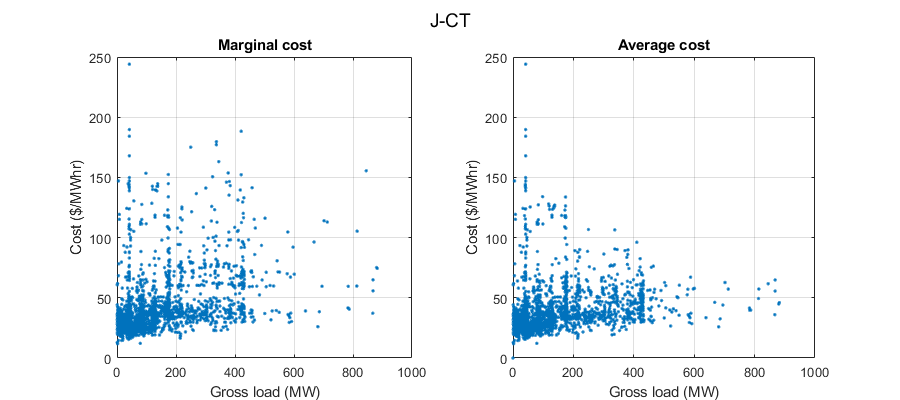

% JCT
figure;
subplot(1,2,1);
scatter(MarPriceTotGenJCT.sum_GrossLoadMW, MarPriceTotGenJCT.max_LBMPMWHr, '.');
title("Marginal cost"); box on; xlabel("Gross load (MW)"); ylabel("Cost ($/MWhr)"); grid on;
axis([0, 1000, 0, 250]);
subplot(1,2,2);
scatter(sumGenPriceJCT.sum_GrossLoadMW,sumGenPriceJCT.AveragePrice, '.');
title("Average cost"); box on; xlabel("Gross load (MW)"); ylabel("Cost ($/MWhr)"); grid on;
axis([0, 1000, 0, 250]);
suptitle("J-CT");
set(gcf, "Units", "Pixels", "Position", [100, 100, 900, 400]);

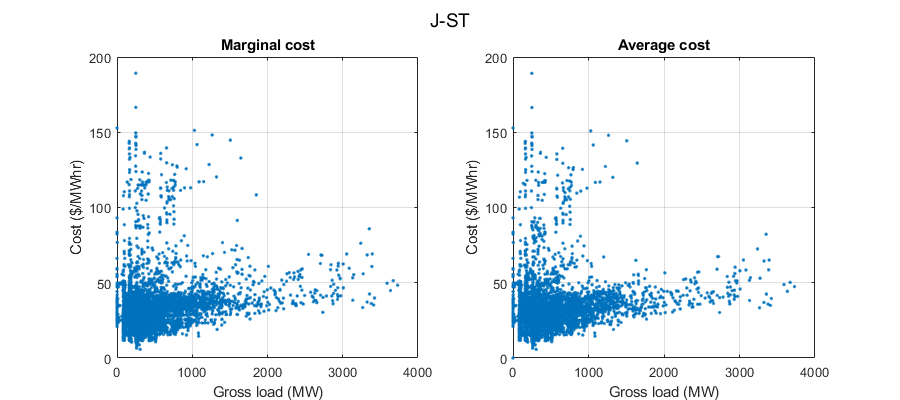

% JST
figure;
subplot(1,2,1);
scatter(MarPriceTotGenJST.sum_GrossLoadMW, MarPriceTotGenJST.max_LBMPMWHr, '.');
title("Marginal cost"); box on; xlabel("Gross load (MW)"); ylabel("Cost ($/MWhr)"); grid on;
axis([0, 4000, 0, 200]);
subplot(1,2,2);
scatter(sumGenPriceJST.sum_GrossLoadMW,sumGenPriceJST.AveragePrice, '.');
title("Average cost"); box on; xlabel("Gross load (MW)"); ylabel("Cost ($/MWhr)"); grid on;
axis([0, 4000, 0, 200]);
suptitle("J-ST");
set(gcf, "Units", "Pixels", "Position", [100, 100, 900, 400]);

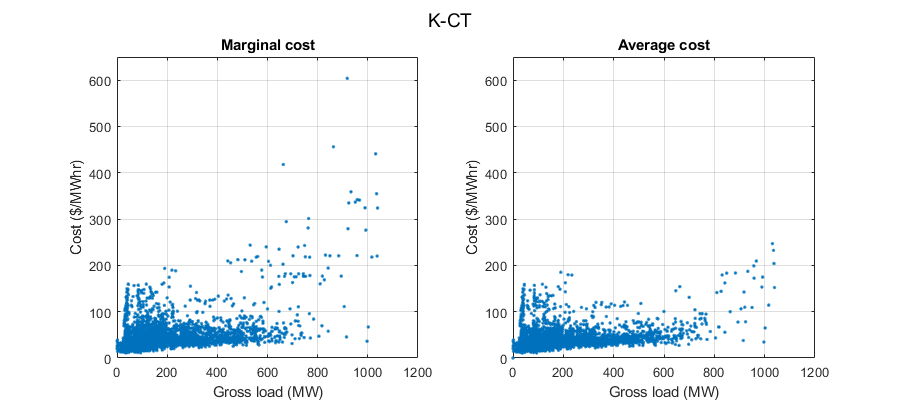

% KCT
figure;
subplot(1,2,1);
scatter(MarPriceTotGenKCT.sum_GrossLoadMW, MarPriceTotGenKCT.max_LBMPMWHr, '.');
title("Marginal cost"); box on; xlabel("Gross load (MW)"); ylabel("Cost ($/MWhr)"); grid on;
axis([0, 1200, 0, 650]);
subplot(1,2,2);
scatter(sumGenPriceKCT.sum_GrossLoadMW,sumGenPriceKCT.AveragePrice, '.');
title("Average cost"); box on; xlabel("Gross load (MW)"); ylabel("Cost ($/MWhr)"); grid on;
axis([0, 1200, 0, 650]);
suptitle("K-CT");
set(gcf, "Units", "Pixels", "Position", [100, 100, 900, 400]);

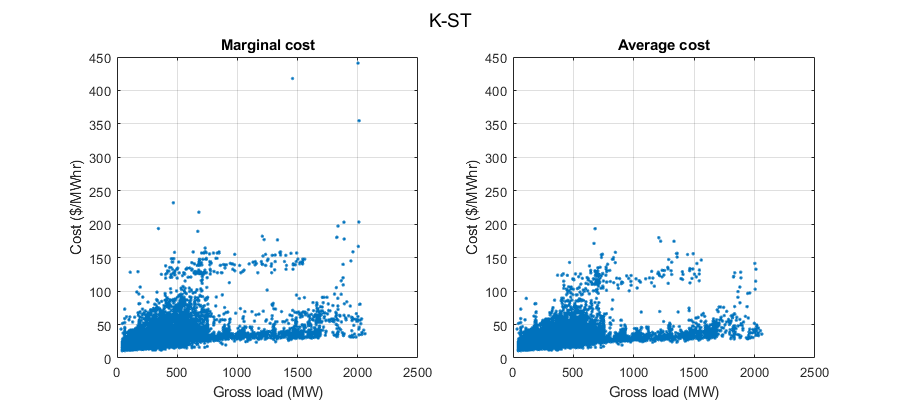

% KST
figure;
subplot(1,2,1);
scatter(MarPriceTotGenKST.sum_GrossLoadMW, MarPriceTotGenKST.max_LBMPMWHr, '.');
title("Marginal cost"); box on; xlabel("Gross load (MW)"); ylabel("Cost ($/MWhr)"); grid on;
axis([0, 2500, 0, 450]);
subplot(1,2,2);
scatter(sumGenPriceKST.sum_GrossLoadMW,sumGenPriceKST.AveragePrice, '.');
title("Average cost"); box on; xlabel("Gross load (MW)"); ylabel("Cost ($/MWhr)"); grid on;
axis([0, 2500, 0, 450]);
suptitle("K-ST");
set(gcf, "Units", "Pixels", "Position", [100, 100, 900, 400]);

MarPriceTotGenA2FCC0101 = MarPriceTotGenA2FCC(MarPriceTotGenA2FCC.Date == "01/01/2019", :)

MarPriceTotGenA2FCC0101 = 19×7 table
       Date       Hour    max_LBMPMWHr    sum_GrossLoadMW    sum_HeatInputMMBtu    sum_GrossRevenue    Dayofyear
    __________    ____    ____________    _______________    __________________    ________________    _________

    01/01/2019      0        26.65                7                 78.85               186.55             1    
    01/01/2019      5        20.44               32                285.56               654.08             1    
    01/01/2019      6        23.12              261                1859.6               6034.3             1    
    01/01/2019      7        21.43              401                2958.3               8593.4             1    
    01/01/2019      8         22.2            

sumGenPriceA2FCC0101 = sumGenPriceA2FCC(sumGenPriceA2FCC.Date == "01/01/2019", :)

sumGenPriceA2FCC0101 = 24×8 table
       Date       Hour    GroupCount    sum_GrossLoadMW    sum_HeatInputMMBtu    sum_GrossRevenue    AveragePrice    Dayofyear
    __________    ____    __________    _______________    __________________    ________________    ____________    _________

    01/01/2019      0         30                7                 78.85               186.55            26.65            1    
    01/01/2019      1         30                0                     0                    0                0            1    
    01/01/2019      2         30                0                     0                    0                0            1    
    01/01/2019      3         30                0         

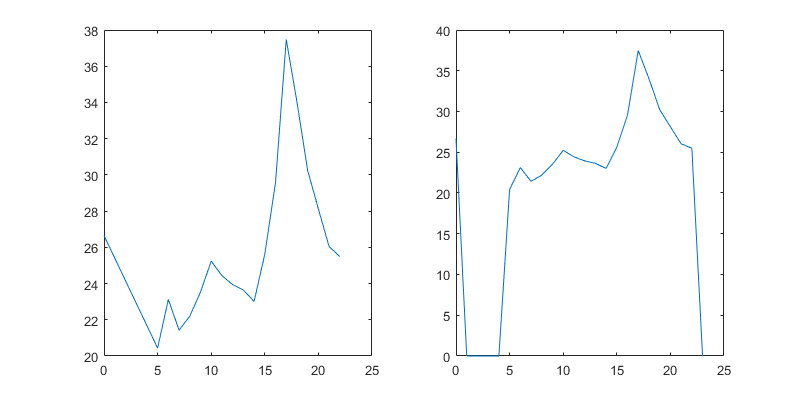

figure;
subplot(1,2,1);
plot(MarPriceTotGenA2FCC0101.Hour, MarPriceTotGenA2FCC0101.max_LBMPMWHr);
subplot(1,2,2);
plot(sumGenPriceA2FCC0101.Hour, sumGenPriceA2FCC0101.AveragePrice);
set(gcf, "Units", "Pixels", "Position", [100, 100, 800, 400]);